# Prepare

clc;clear all;close all;

## Load mri

load mri;
MRI_im=squeeze(D);

## axial

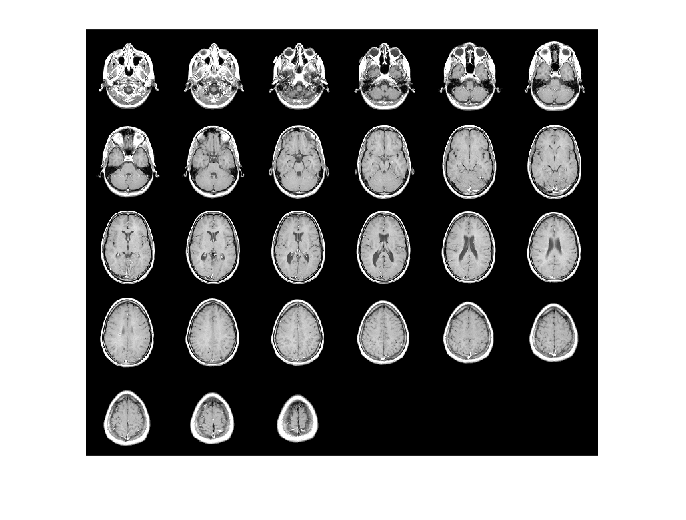

for i=1:27
    axial(:,:,1,i)=MRI_im(:,:,i);
end
figure
montage(axial,map)

## coronal

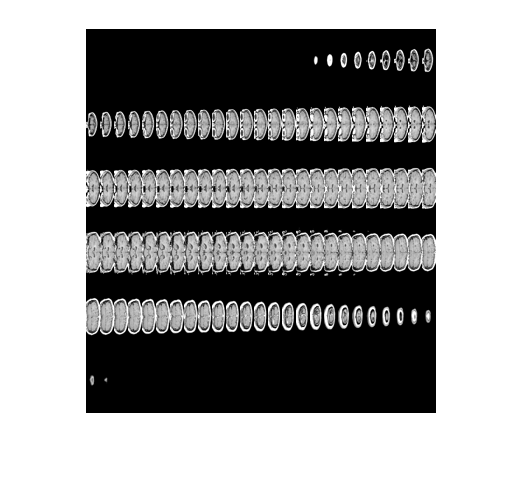

for i=1:128
    coronal(:,:,1,i)=MRI_im(i,:,:);
end
figure
montage(coronal,map)

## sagital

for i=1:128
    sagital(:,:,1,i)=MRI_im(i,:,:);
end
figure
montage(sagital,map)

## Visualizing 3d image

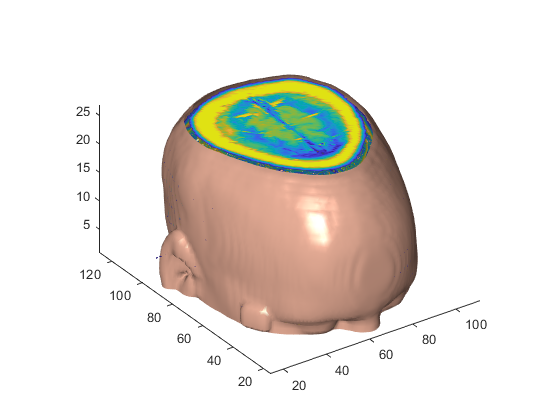

figure
contourslice(MRI_im,[],[],[1:3:27],8); 
MRI_ims = smooth3(MRI_im);
hiso = patch(isosurface(MRI_ims,5),...
    'FaceColor',[1,.75,.65],...
    'EdgeColor','none');
isonormals(MRI_ims,hiso)
hcap = patch(isocaps(MRI_im,5),...
    'FaceColor','interp',...
    'EdgeColor','none');
view(-35,30) 
axis('tight'); 
 daspect([1,1,.4])
 lightangle(-45,30);
 lighting gouraud
 hcap.AmbientStrength = 0.6;
 hiso.SpecularColorReflectance = 0;
 hiso.SpecularExponent = 50;